# The free surface model by Nicholas Tabelert

# 
$$\frac{d \tilde y}{d \tilde x} \ = \ \mu_i \ + \ \frac{\mu_w}{L}\left(\frac{d \omega^2}{g}\right)^{\frac{1}{4}}R \ \left[ \ 1 - \tilde x^2 - \tilde y^2\ \right]^{\frac{1}{2}}$$


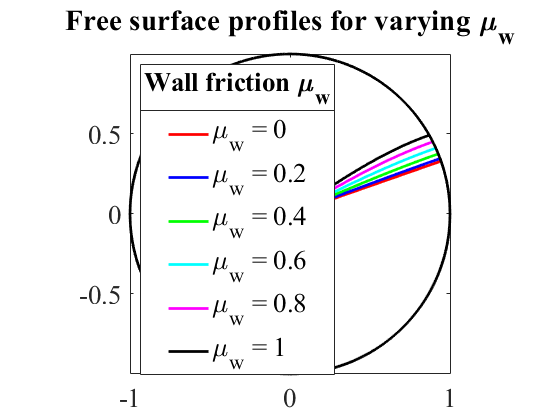

clear
robust = 1;
for i = [1:6]
m = [0 0.2 0.4 0.6 0.8 1];
used_color = 'rbgcmk';
R = 1;d = 3e-3; g = 9.81; L = 0.4; mu_i = 0.35;mu_w = m(i);
omega = m(i);
syms x y
ode = mu_i + R*(mu_w/L)*(d*omega^2/g)^(1/4)*(1 - x^2 - y^2);
RRR = matlabFunction(ode,'vars',{x,y});
YO = 0;
[Xu,Yu] = ode45(RRR,[0, R],YO);
[Xa,Ya] = ode45(RRR,[0, -R],YO);
XX = linspace(-R,R,1000);
domu = sqrt(R.^2 - XX.^2);
doma = -sqrt(R.^2 - XX.^2);
X_intercept_upper = intersection_function(XX,domu,Xu,Yu,robust);
X_intercept_lower = intersection_function(XX,doma,Xa,Ya,robust);
[Xu,Yu] = ode45(RRR,[0, X_intercept_upper],YO);
[Xa,Ya] = ode45(RRR,[0, X_intercept_lower],YO);
plot(XX,domu,'k',"LineWidth",2,'DisplayName',['\mu_w = ',num2str(mu_w)],'HandleVisibility','off')
hold on
plot(XX,doma,'color','k',"LineWidth",2,'DisplayName',['\mu_w = ',num2str(mu_w)],'HandleVisibility','off')
hold on
plot(Xu,Yu,used_color(i),'LineWidth',2,'DisplayName',['\mu_w = ',num2str(mu_w)],'HandleVisibility','on')
hold on
plot(Xa,Ya,used_color(i),'LineWidth',2,'DisplayName',num2str(mu_w),'HandleVisibility','off')
title('Free surface profiles for varying \mu_w','FontSize',25)
axis equal
end
leg = legend('show','Location','northwest','FontSize',20);
title(leg,'Wall friction \mu_w',"FontSize",20)
axis tight
set(gca,'XMinorTick','off','YMinorTick','off', 'FontSize', 20, 'FontName', 'Times New Roman')